# 1D Target Tracking

**Author**: Michel Barbeau

**Version**: February 11, 2024

## Sample Execution 1

`Number of instants:  10`

`Target positions:  [1 3 5 2 1 1 3 0 0 6]`

`Info: {'constraint_labels': ['p_6', 'min_3', 'l_6', 'l_5', 'p_0', 'min_8', 'min_2', 'p_5', 'p_8', 'u_4', 'l_3', 'p_1', 'p_4', 'l_1', 'min_1', 'l_8', 'l_2', 'min_6', 'p_7', 'u_9', 'u_0', 'u_2', 'u_1', 'u_7', 'u_8', 'min_5', 'u_6', 'p_2', 'u_5', 'min_9', 'l_7', 'l_4', 'u_3', 'p_3', 'min_4', 'min_7', 'l_9', 'min_0', 'l_0'], 'qpu_access_time': 31901, 'charge_time': 4687119, 'run_time': 4687119, 'problem_id': 'da018e96-2982-454e-b539-0630a499919a'}`

`Sample: {'v_0': -2.0, 'v_1': 2.0, 'v_2': 1.0, 'v_3': -1.0, 'v_4': 0.0, 'v_5': -2.0, 'v_6': 1.0, 'v_7': 0.0, 'v_8': 2.0, 'v_9': 2.0, 'x_0': 3.0, 'x_1': 1.0, 'x_2': 3.0, 'x_3': 4.0, 'x_4': 3.0, 'x_5': 3.0, 'x_6': 1.0, 'x_7': 2.0, 'x_8': 2.0, 'x_9': 4.0}`

`Tracking score: 40.0`

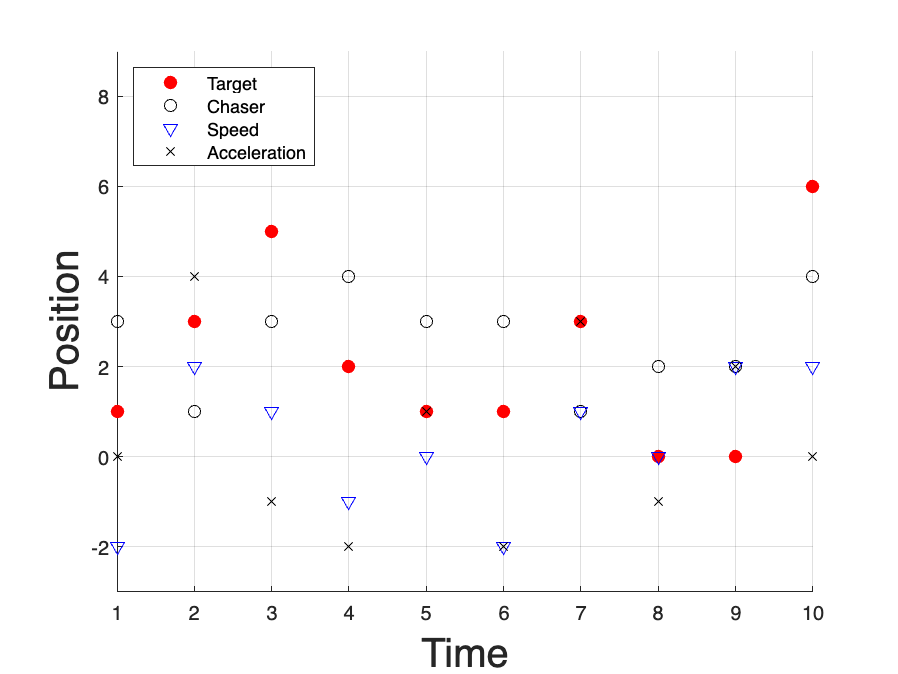

% number of instants
n = 10;
% Speed
v = [-2 2 1 -1 0 -2 1 0 2 2]; % last item not used in constraints
figure;
% title('1D Target Tracking');
hold on;  
% Target
plot(1:10,...
     [1 3 5 2 1 1 3 0 0 6],'.','markersize',20,'color','red');
% Chaser
plot(1:10,...
     [3 1 3 4 3 3 1 2 2 4],'o','color','black');
% Speed
plot(1:10,...
     v,'v','color','blue');
legend('Target','Chaser','Speed','Location','southeast')
% Acceleration
plot(1:10,...
     [0 v(2:end)-v(1:end-1)],'kx');
legend('Target','Chaser','Speed','Acceleration','Location','northwest')
ylim([-3 9])
yl = ylabel('Position');
set(yl, 'FontSize', 20) 
xl = xlabel('Time');
set(xl, 'FontSize', 20) 
% ylim([0 34]);
hold off;
grid on;
f = gcf;
cd '/Users/michelbarbeau/Dropbox/MyProjects/2024/D-Wave'
exportgraphics(f,'1DTargetTracking.png');